# Prediction with NLD

## Obtain spike triggering ensembles

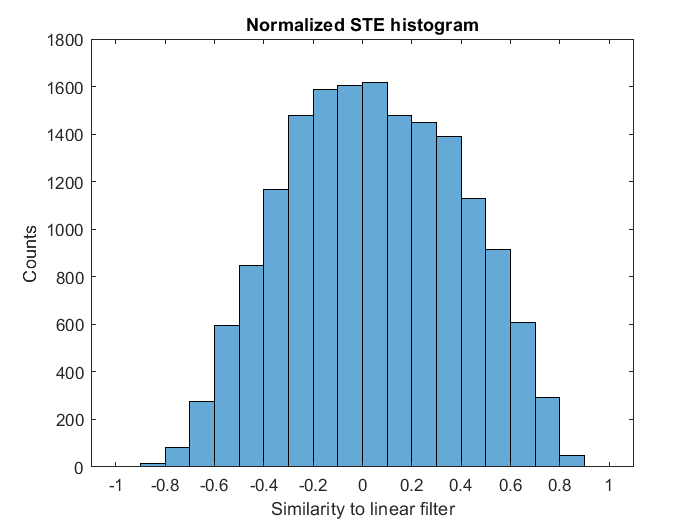

linearFilter = sig_evec(:,1);
% linearFilter = STA;

stimulus_test = stimulus(:,8*fs+1:end);
raster_data_test = raster_data(:,8*fs+1:end);
mean_gcfr = P.avg_gcfr(start_stim:stop_stim);
mean_gcfr_model = mean_gcfr(1:8*fs);
mean_gcfr_test_set = mean_gcfr(8*fs+1:end-1);
mean_FR = numSpikes/(nTrials*ON_dur);

spike_window = P.fs*1e-3;

locs_ref = find(raster_data_model(1,:)==1); %spikes of first trial only
ref = locs_ref(1);

stim_pattern = zeros(length(locs_ref),length(linearFilter));
Pc_spike_stim = nan(1,length(locs_ref));
FR_spike_stim = nan(1,length(locs_ref));
similarity_STA = nan(length(locs_ref),1);
similarity_EVec1 = nan(length(locs_ref),1);
similarity_EVec2 = nan(length(locs_ref),1);

similarity_STA_corrcoef = nan(length(locs_ref),1);
similarity_EVec1_corrcoef = nan(length(locs_ref),1);

% Nspikes = length(locs_ref);

time_train_set = time(1:8*fs);
% figure;
% ax1 = subplot(3,1,1); plot(time_train_set, mean(stimulus_model,1)); hold on;
% ylabel('Avg stimulus (deg)');
% ax2 = subplot(3,1,2); hold on;
% ylabel('Trials #');
% ax3 = subplot(3,1,3); plot(time_train_set, mean_gcfr_model); hold on;
% ylabel('Firing rate (Hz)');
% xlabel('Time (s)');
% linkaxes([ax1,ax2,ax3], 'x');

for j = 1:length(all_spike_triggers)
            
            similarity_STA(j) = dot(linearFilter,(all_spike_triggers(j,:))')/(norm(all_spike_triggers(j,:))*norm(linearFilter));%/dot(linearFilter,stimulus_model_prior(1,:));
%             similarity_EVec1(j) = dot(eVec1Norm, (stim_pattern(j,:))');
%             similarity_EVec2(j) = dot(eVec2Norm, (stim_pattern(j,:))');
            similarity_PSE(j) = dot(linearFilter,(stimulus_prior(j,:))')/(norm(stimulus_prior(j,:))*norm(linearFilter));
        
end



edges = -1:0.1:1;

figure;
histogram(similarity_STA,'BinEdges',edges);
xlabel('Similarity to linear filter');
ylabel('Counts');
title('Normalized STE histogram');

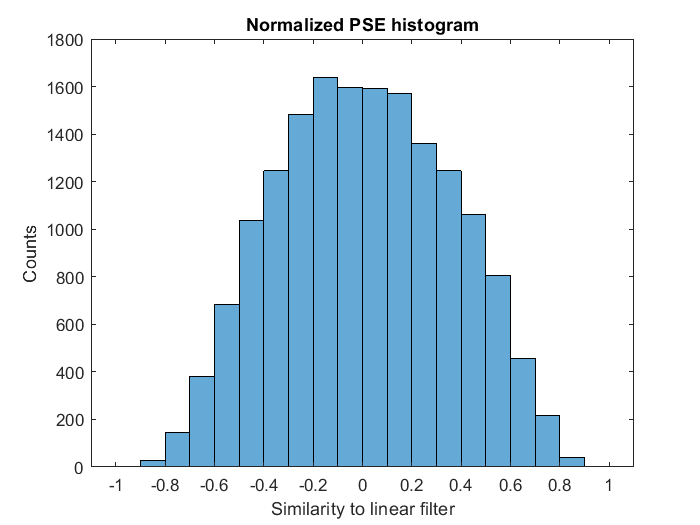


figure;
histogram(similarity_PSE,'BinEdges',edges);
xlabel('Similarity to linear filter');
ylabel('Counts');
title('Normalized PSE histogram');


[N_STE,ed] = histcounts(similarity_STA, edges); 
[N_PSE,~] = histcounts(similarity_PSE, edges);
BinCenters = edges(1:end-1) + diff(edges)/2;
N_STE_norm = N_STE/sum(N_STE);
N_PSE_norm = N_PSE/sum(N_PSE);

N = N_STE_norm./N_PSE_norm; %/numSpikes
ind = find(N_STE <50 | N_PSE < 50 | isnan(N));
N(ind) = [];
BinCenters(ind) = [];
FR = N*mean_FR;

## NLD function


figure;
[f_pspike, gof] = fit(BinCenters', FR','poly2') %, 'Exclude', FR<0.001 | isnan(FR));

f_pspike =      Linear model Poly2:
     f_pspike(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      -1.642  (-23.2, 19.91)
       p2 =       35.96  (27.13, 44.8)
       p3 =       92.59  (86.46, 98.72)

gof = struct with fields:
           sse: 739.0521
       rsquare: 0.8562
           dfe: 13
    adjrsquare: 0.8340
          rmse: 7.5399


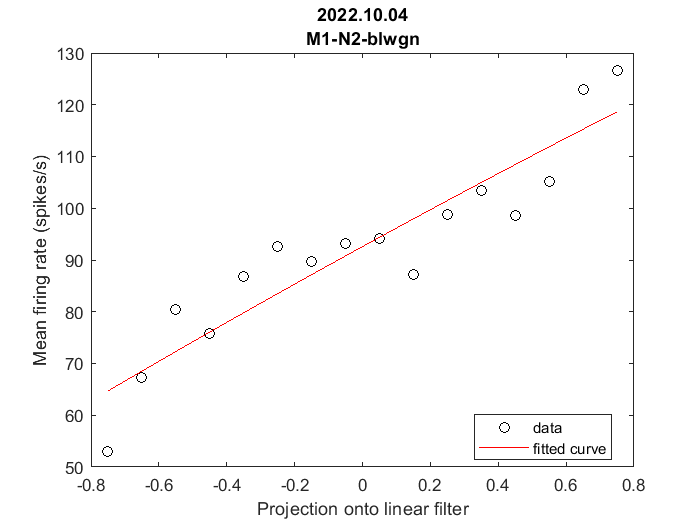

plot(f_pspike,BinCenters,FR','ko');
xlabel('Projection onto linear filter');
ylabel('Mean firing rate (spikes/s)');
legend('Location', 'best');
title(replace([P(1).date P(1).filename], '_','-'));
hold on;
text(15,10,string(["rsquare =" gof.rsquare]));

gof

gof = struct with fields:
           sse: 739.0521
       rsquare: 0.8562
           dfe: 13
    adjrsquare: 0.8340
          rmse: 7.5399


## Prediction with projection

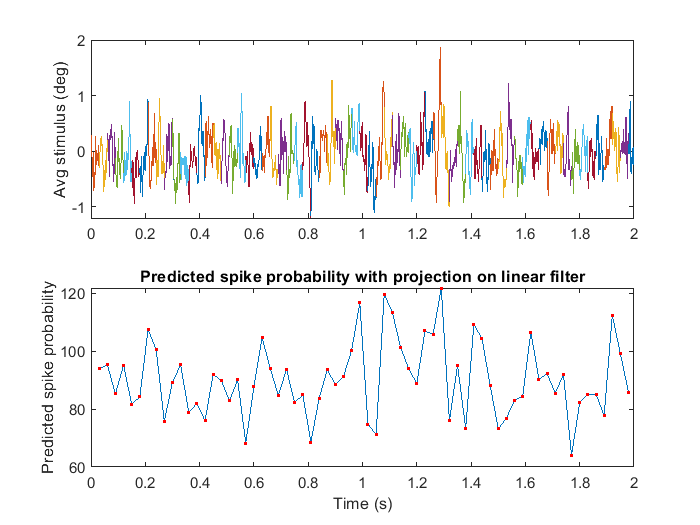

predStepWin = 30e-3*fs; % 1 ms
% predTable = table(spikeloc, FR, Pspike);
time_test_set = time(1:2*fs);

figure;
ax1 = subplot(2,1,1); plot(time_test_set, mean(stimulus_test,1)); hold on;
ylabel('Avg stimulus (deg)');

% ax2 = subplot(3,1,2); plot(time_test_set, )
% ax2 = subplot(2,1,2); plot(time_test_set, mean_gcfr_test_set); hold on;
% xlabel('Time (s)');
% ylabel('Firing rate (Hz)');


pspikePred = [];
timestamps = [];

for iwin = 1:predStepWin:(length(stimulus_test)-stim_window*fs-1)
    test_stim = mean(stimulus_test(:,iwin:iwin+stim_window*fs),1);
    subplot(2,1,1); plot(time_test_set((iwin:iwin+stim_window*fs)), test_stim); hold on;
    similarity = dot(test_stim, linearFilter)/(norm(test_stim)*norm(linearFilter));
    timestamps = [timestamps iwin+stim_window*fs+1];
    pspikePred = [pspikePred f_pspike(similarity)];
end


ax2 = subplot(2,1,2);plot(time_test_set(timestamps), pspikePred, 'Marker',".","MarkerEdgeColor",'r' );
hold on;
ylabel('Predicted spike probability');
title('Predicted spike probability with projection on linear filter')
xlabel('Time (s)');

## Actual spike probability for test dataset

locs_ref = find(raster_data_test(1,:)==1); %spikes of first trial only
ref = locs_ref(1);
FR_actual = [];

for j = 1:length(locs_ref)
        ref = locs_ref(j);
        
        if ref>stim_window*P.fs && (ref+spike_window)<length(stimulus_model)
            [spike_rows_trials, locs] = find(raster_data_test(:,ref-spike_window : ref+spike_window)==1);
            FR_actual(j) = mean_gcfr_test_set(j);
 
        end      
end
% subplot(2,1,2); plot(locs_ref/fs, FR_actual, 'Marker',".","MarkerEdgeColor",'k' );
ax2 = subplot(2,1,2); plot(time_test_set, mean_gcfr_test_set, 'k');
linkaxes([ax1,ax2], 'x');

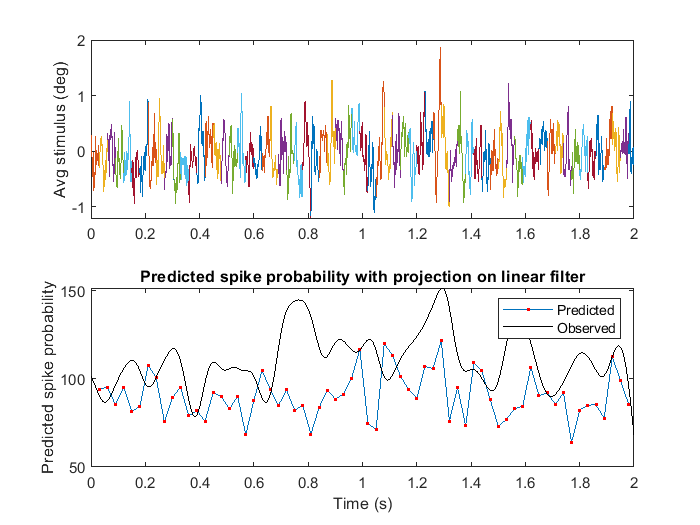

legend('Predicted','Observed');